# Fahrplansimulation für die Auslegung der Traktionsbatterie

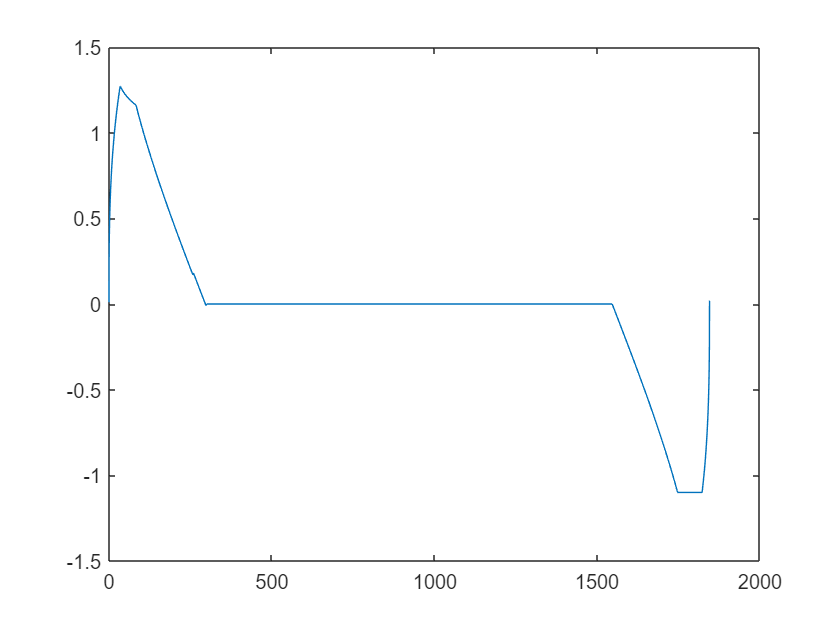

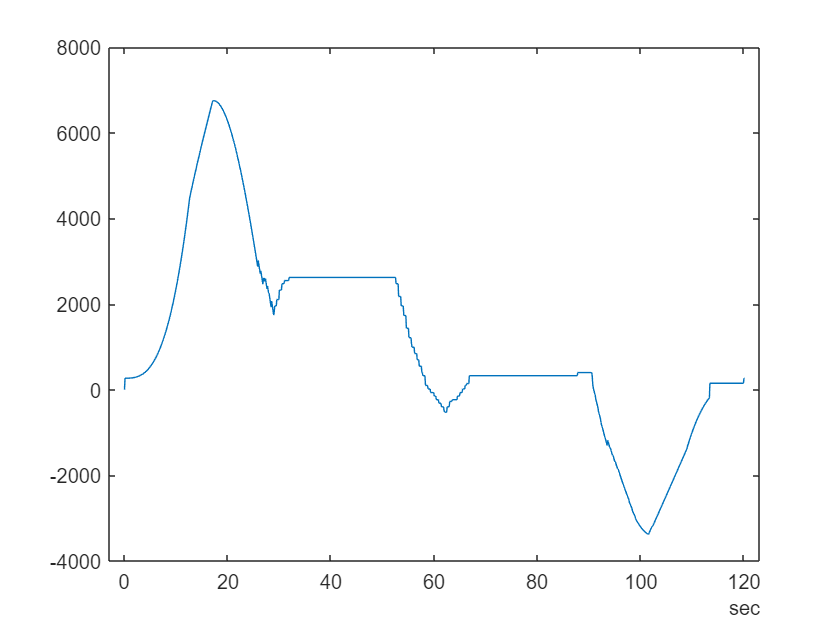

% V5.2 für die Auslegung der Traktionsbatterien

% setting delay probability of each train (0.1 = 10% chance, 1 = 100% chance)
Delay = 0;

% Zufällige Verspätung generieren
if(rand(1,1) < Delay)
    tDelay = (rand(1,1) * (1-0) + 0) * 60;
    Fahrtzeit = Fahrtzeit - tDelay;
end
                
% Aufruf der Funktion für die Simulation der Zugfahrt
[Str_sim, Fz_sim, CompData] = Fahrtsimulation10(Str, FZ, const, OptimizationData);

CompData.time = seconds(transpose(0:0.1:-0.1 + (length(Str_sim.Strecke)/10)));
%CompData.time.Format = 'hh:mm:ss:S'
CompleteData = CompData; % Simulierte Daten werden in Strucktur gespeichert

% a = [1 2 3 4 6]

a =      1     2     3     4     6


% 
% ismember(4,a)

ans = logical
   1


% n = [];
% for k = 1:numel(fn)
%     if(ismember((height(CompleteData.(fn{k}))), n))
%         n = n;
%     else
%         n = [n height(CompleteData.(fn{k}))];
%     end
% end